% script for modeling multiple elongation times
% Just generates sample traces
% I just keep this around in case I want to quickly mess with stuff
% should be run from src folder

trans_mat = [-0.0215,  0.0095,  0; ...
         0.0215, -0.0180,  0.0440; ...
         0.0000,  0.0085, -0.0440];
fluo_per_rna = 35;
time_res = 20;
rna_per_sec = [.0001, .186, .372];
points_per_trace = 200;
num_traces = [50,50,50];
num_states = 3;
MS2_rise_time = [40,40,40];
init_dist = [1,0,0];
noise = 500;
elong_times = [120,160,200];
traces = {};

for i = 1:length(elong_times)
    elong = elong_times(i);
    nt = num_traces(i);
    rt = MS2_rise_time(i);
    new_traces = gen_data(elong, time_res, points_per_trace, nt, ...
        num_states, trans_mat, rna_per_sec, fluo_per_rna, rt, ...
        init_dist, noise);
    traces = [traces, new_traces];
end

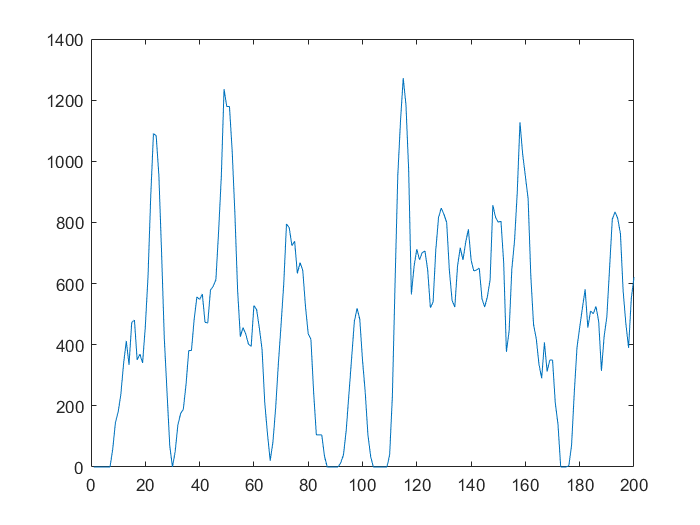

i = 12;
figure();
plot(traces{i});

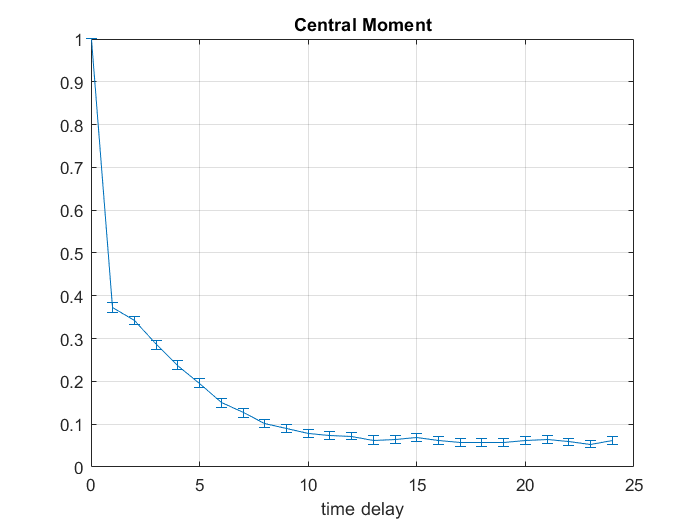

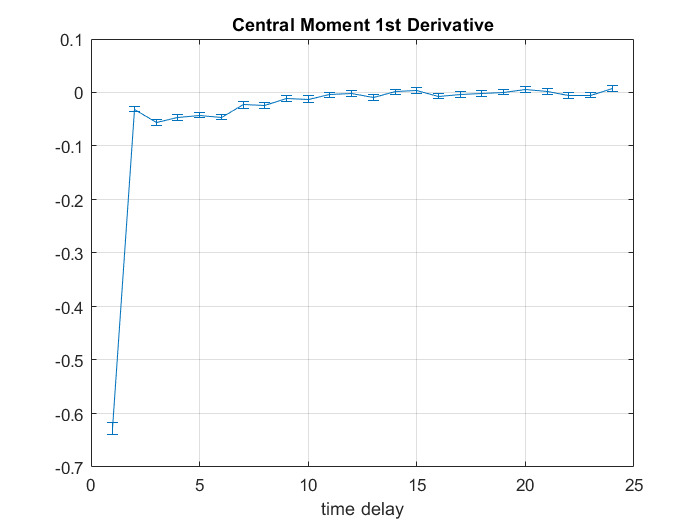

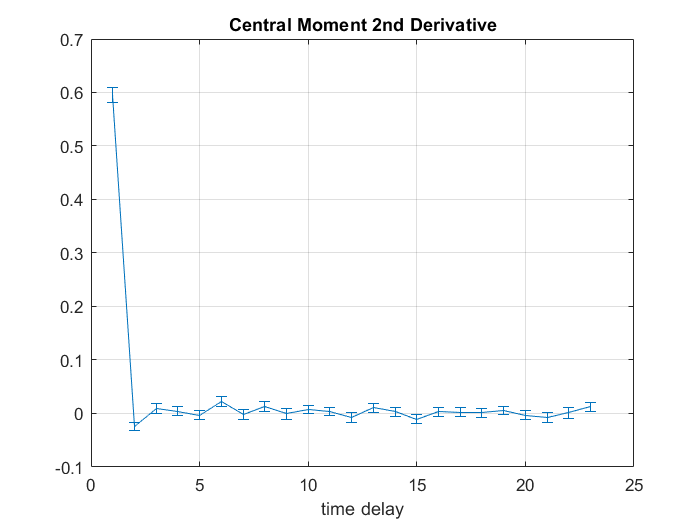

gen_auto_cor(traces,true,true,true,true,25,0);